# **변경사항**

### 2020.08.25

- spike 개수가 2 이상인 경우에만 sync score 계산하도록 수정

- network plot에서 node 크기를 키우고 채널 번호가 보이도록 수정

# **Python 설치 및 설정 방법**

**(윈도우 기준)**

- [https://www.python.org/downloads/windows/](https://www.python.org/downloads/windows/) 에서 python 3.7, 3.8, 3.9 버전 중 하나를 windows installer로 다운로드받습니다.

- [https://wikidocs.net/8](https://wikidocs.net/8) 링크의 설명을 따라하여 설치를 완료합니다. Add Python 3.x to PATH 옵션을 꼭 체크합니다.

- windows powershell을 실행합니다. 윈도우 10이면 기본적으로 설치되어 있습니다.

- 입력창에 `python`을 입력하여 python을 실행합니다. python 버전이 설치한 버전과 일치하는지 확인합니다.

- 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다(저는 macos에서 진행했기 때문에 윈도우와 파이썬 경로가 다릅니다).

          6. powershell을 종료하고 다시 실행합니다. 이번에는 python을 실행하지 않고, powershell 창에 바로 아래 내용을 한 줄씩 입력하고 엔터를 칩니다.  각 명령어는 패키지 하나를 설치하는 명령어입니다. 실행되지 않으면 pip3 대신 pip를 입력합니다.

`*수정: pickle 패키지는 파이썬 3.6부터 기본으로 포함되어 있으므로 설치하지 않아도 됩니다.`

`pyspike 설치 시 io.h 파일이 없다는 오류 메시지가 나오면 `[`https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/`](https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/)` 에서 windows 10 sdk를 설치합니다.`

# **작업 절차**

## **1.multi-pixel retina data 불러와 channel object 만들기**

**1.1. 파일 전체를 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/mac/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 소요시간 측정. 적지 않은 시간 소요됨

경과 시간은 65.678399초입니다.


## 2. networkAnalyzer 클래스 인스턴스 생성

**class **`networkAnalyzer`

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9");

ans =   PythonEnvironment - 속성 있음:

          Version: "3.9"
       Executable: "/usr/local/opt/python@3.9/bin/python3.9"
          Library: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


## 3. 채널 object를 networkAnalyzer에 입력

na.addChannels(reader);

Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×4 double]
     syncScores: []
      nConnects: []


na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×4 double]
     syncScores: []
      nConnects: []


## 4. 채널 위치 입력

method `setChannelPosition2d`

input argument:

- channel number

- 해당 channel의 x좌표

- 해당 channel의 y좌표

- 해당 channel의 z좌표

좌표는 좌표평면의 1사분면을 생각하면 됩니다. (0,0)의 한 칸 위가 (0,1)이고 한 칸 오른쪽이 (1,0)입니다. 아래 코드로 설정한 위치를 그림으로 그리면 아래 그림처럼 됩니다.

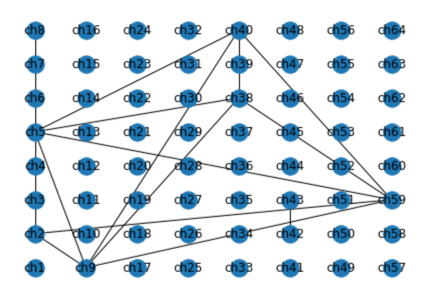

%                 channlNum x  y  z
na.setChannelPosition3d(1 , 0, 0, 0)
na.setChannelPosition3d(2 , 0, 1, 0)
na.setChannelPosition3d(3 , 0, 2, 0)
na.setChannelPosition3d(4 , 0, 3, 0)
na.setChannelPosition3d(5 , 1, 0, 0)
na.setChannelPosition3d(6 , 1, 1, 0)
na.setChannelPosition3d(7 , 1, 2, 0)
na.setChannelPosition3d(8 , 1, 3, 0)
na.setChannelPosition3d(9 , 2, 0, 0)
na.setChannelPosition3d(10, 2, 1, 0)
na.setChannelPosition3d(11, 2, 2, 0)
na.setChannelPosition3d(12, 2, 3, 0)
na.setChannelPosition3d(13, 3, 0, 0)
na.setChannelPosition3d(14, 3, 1, 0)
na.setChannelPosition3d(15, 3, 2, 0)
na.setChannelPosition3d(16, 3, 3, 0)

na.setChannelPosition3d(17,  0, 0, 1.5)
na.setChannelPosition3d(18,  0, 1, 1.5)
na.setChannelPosition3d(19,  0, 2, 1.5)
na.setChannelPosition3d(20,  0, 3, 1.5)
na.setChannelPosition3d(21,  1, 0, 1.5)
na.setChannelPosition3d(22,  1, 1, 1.5)
na.setChannelPosition3d(23,  1, 2, 1.5)
na.setChannelPosition3d(24,  1, 3, 1.5)
na.setChannelPosition3d(25,  2, 0, 1.5)
na.setChannelPosition3d(26,  2, 1, 1.5)
na.setChannelPosition3d(27,  2, 2, 1.5)
na.setChannelPosition3d(28,  2, 3, 1.5)
na.setChannelPosition3d(29,  3, 0, 1.5)
na.setChannelPosition3d(30,  3, 1, 1.5)
na.setChannelPosition3d(31,  3, 2, 1.5)
na.setChannelPosition3d(32,  3, 3, 1.5)

na.setChannelPosition3d(33,  0, 0, 3)
na.setChannelPosition3d(34,  0, 1, 3)
na.setChannelPosition3d(35,  0, 2, 3)
na.setChannelPosition3d(36,  0, 3, 3)
na.setChannelPosition3d(37,  1, 0, 3)
na.setChannelPosition3d(38,  1, 1, 3)
na.setChannelPosition3d(39,  1, 2, 3)
na.setChannelPosition3d(40,  1, 3, 3)
na.setChannelPosition3d(41,  2, 0, 3)
na.setChannelPosition3d(42,  2, 1, 3)
na.setChannelPosition3d(43,  2, 2, 3)
na.setChannelPosition3d(44,  2, 3, 3)
na.setChannelPosition3d(45,  3, 0, 3)
na.setChannelPosition3d(46,  3, 1, 3)
na.setChannelPosition3d(47,  3, 2, 3)
na.setChannelPosition3d(48,  3, 3, 3)

na.setChannelPosition3d(49, 0, 0, 4.5)
na.setChannelPosition3d(50, 0, 1, 4.5)
na.setChannelPosition3d(51, 0, 2, 4.5)
na.setChannelPosition3d(52, 0, 3, 4.5)
na.setChannelPosition3d(53, 1, 0, 4.5)
na.setChannelPosition3d(54, 1, 1, 4.5)
na.setChannelPosition3d(55, 1, 2, 4.5)
na.setChannelPosition3d(56, 1, 3, 4.5)
na.setChannelPosition3d(57, 2, 0, 4.5)
na.setChannelPosition3d(58, 2, 1, 4.5)
na.setChannelPosition3d(59, 2, 2, 4.5)
na.setChannelPosition3d(60, 2, 3, 4.5)
na.setChannelPosition3d(61, 3, 0, 4.5)
na.setChannelPosition3d(62, 3, 1, 4.5)
na.setChannelPosition3d(63, 3, 2, 4.5)
na.setChannelPosition3d(64, 3, 3, 4.5)


na.positions

ans =      1     1     0     0     0
     2     2     0     1     0
     3     3     0     2     0
     4     4     0     3     0
     5     5     1     0     0
     6     6     1     1     0
     7     7     1     2     0
     8     8     1     3     0
     9     9     2     0     0
    10    10     2     1     0


## 5. 모든 채널에 bandpass 적용하고 spike detection 수행

summary_examples_firing_rate.mlx 파일의 [0.4. bandpass filter 적용] [0.5. (method) `detectSpikes] 섹션 참조`

na.bandPass([300,3000])
na.detectSpikes(4,2,2);

number of spikes found : 61
number of spikes found : 131
number of spikes found : 140
number of spikes found : 313
number of spikes found : 351
number of spikes found : 86
number of spikes found : 82
number of spikes found : 175
number of spikes found : 147
number of spikes found : 108
number of spikes found : 29
number of spikes found : 322
number of spikes found : 348
number of spikes found : 336
number of spikes found : 353
number of spikes found : 15
number of spikes found : 177
number of spikes found : 87
number of spikes found : 319
number of spikes found : 351
number of spikes found : 348
number of spikes found : 53
number of spikes found : 77
number of spikes found : 40
number of spikes found : 75
number of spikes found : 100
number of spikes found : 152
number of spikes found : 322
number of spikes found : 278
number of spikes found : 186
number of spikes found : 160
number of spikes found : 17
number of spikes found : 163
number of spikes found : 276
number of spikes found : 

## 6. sync score matrix heatmap

figure 3 a, b, c, d, e의 (i)

pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도(혹은 거리)를 측정합니다.

spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 함수가 작동하지 않습니다. 따라서 이 때에는 거리 계산값이 NaN이 되도록 함수를 수정하였습니다(2022.08.24)

NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

아래 사항은 아직 구현하지 않았습니다(reference 12페이지에 있는 내용) 

Since two spike trains with uniformly random activity may exhibit relatively high synchrony merely due to randomness, the SPIKE-distance from recorded data was normalized to random samples generated computationally. That is, for a pair of electrodes with $n_1$ and $n_2$ spikes,

- random spike trains were generated by **sampling $n_1$ and $n_2$ points uniformly at random in a 10-minute timeline.**

- This process was **repeated 1,000 times**, and the **average normalized score** is reported.

filepath_score_matrix = "/Users/mac/GitHub/neurosignal-matlab/score_matrix.npy"

filepath_positions = "/Users/mac/GitHub/neurosignal-matlab/positions.pkl"

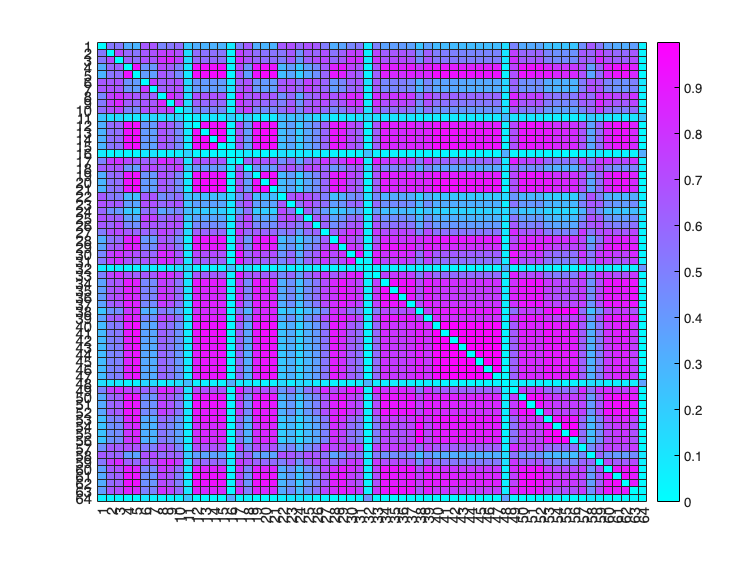

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: 64
        distMat: [64×64 double]
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×5 double]
     syncScores: [64×64 table]
      nConnects: []


ans =          0    0.5208    0.5274    0.3209    0.2913    0.6531    0.6573    0.4746    0.5192    0.5680    0.2222    0.3133    0.2934    0.3023    0.2899    0.0789    0.4874    0.6351    0.3158    0.2913    0.2934    0.6491    0.6812    0.5941    0.6765    0.6460    0.5070    0.3185    0.3540    0.4696    0.5249    0.0769    0.4911    0.3561    0.3762    0.3859    0.3614    0.2285    0.3582    0.2679    0.2661    0.2675    0.2641    0.2641    0.2614    0.2603    0.2603    0.1299    0.4777    0.3324
    0.5208         0    0.7085    0.5856    0.5353    0.6452    0.6761    0.7516    0.7410    0.6862    0.1250    0.5695    0.5428    0.5567    0.5372    0.0274    0.7532    0.6514    0.5689    0.5394    0.5344    0.5326    0.6442    0.4327    0.6311    0.5974    0.6784    0.5430    0.6259    0.7508    0.7491    0.0541    0.7279    0.6290    0.6581    0.6667    0.6219    0.4272    0.6272    0.5058    0.5029    0.4943    0.4774    0.4737    0.4764    0.4783    0.4783    0.0952    0.7508   

na.spikeDist()

###  network mapping 을 위해 계산하는 parameter 확인

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na.syncScores

ans = 64×64 table
               node1       node2       node3       node4       node5       node6       node7      node8       node9       node10      node11      node12      node13      node14      node15      node16      node17      node18      node19      node20      node21     node22      node23      node24      node25      node26     node27      node28      node29      node30      node31      node32     node33      node34      node35      node36      node37      node38      node39      node40      node41      node42      node43      node44      node45      node46      node47      node48      node49      node50      node51      node52      node53      node54      node55      node56     node57      node58     node59      node60      node61      node62      node63      node64 
              ________    ________    ________    ________    ________    ________    _______    ________    ________    ________    ________    ________    ________    ________    ________    ________    ____

아래는 각 노드에 연결된(sync score 0.5 이상) 노드의 개수를 나타냅니다.

na.nConnects

ans = 64×1 table
              number of connected
              ___________________

    node1             16         
    node2             46         
    node3             51         
    node4             48         
    node5             47         
    node6             23         
    node7             22         
    node8             55         
    node9             52         
    node10            34         
    node11             0         
    node12            47         
    node13            47         
    node14            47         
    node15            47         
    node16             0         


## 7. network plot(3d)

method `louvain()`

figure 3 a, b, c, d, e의 (ii)

matlab에서 python을 통해 networkx로 네트워크를 만들고 louvain-python으로 community detection을 하는 것까지는 별 문제가 없으나,

네트워크 모양을 plot으로 그리는 것은 matplotlib 라이브러리를 써야 하는데, 이상하게도 matlab에서 연동이 잘 안됩니다.

차선책으로, score matrix를 파일로 저장한 다음 아예 파이썬 스크립트를 만들고 matlab에서는 해당 파이썬 스크립트를 실행하는 명령만 내리도록 조치하였습니다.

plot은 이 파일이 있는 경로에 `networkfig.html`로 저장됩니다.

sync score 0.5 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

Nodes with the same color (i.e., electrodes) represented the same community network.

The color-mapped synchronization score ranged from 0 (blue) to 1 (red).

In addition, the larger the number of connected electrodes becomes, the larger the size of the node becomes. 

node colors are entered as varaious formats, including hexa code, rgb code, or names css colors: 

see "Built-In Sequential Color scales" in  [https://plotly.com/python/builtin-colorscales/](https://plotly.com/python/builtin-colorscales/) 

degree_lim = [10, 30] % look at na.nConnects and determine the degree range

degree_lim =     10    30


edge_lim = [0.6, 0.8] % the min value must be larger than 0.5

edge_lim =     0.6000    0.8000




%        basic_size,  multiplier     colorscale_edge,       colorscale_node        degree_lim,       edge_lim
na.louvain(10,         20,            'teal'                    ,'oranges',         degree_lim,        edge_lim)

filepath_node_sizes = "/Users/mac/GitHub/neurosignal-matlab/node_sizes.npy"

filepath_colors = "/Users/mac/GitHub/neurosignal-matlab/colors.pkl"

filepath_lims = "/Users/mac/GitHub/neurosignal-matlab/lims.pkl"

ans = 0